# MatHH: Exercises (with solutions)

This file contains some exercises about using the MatHH framework to create Rule-based Selection Hyper-heuristic (RBSHH) models. This file also contains the solutions to such problems.

## Cleanup:

clc
clear
close all

## Package loading:

addpath('..\..\src\') % Adds common functionality (HH models)
addpath(genpath('..\extended\Utils')) % Adds common utilities package
addpath(genpath('..\extended\Domains\JSSP')) % Adds JSSP package (required for default mode)

## Instance loading:

### Load instances for testing

% ------ First set of training instances (5x5)
instanceDataset = '..\..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E02\instanceDataset.mat';
load(instanceDataset);
JSSPInstancesFirst = num2cell(allInstances); % Stores instances as cell array
fprintf('Loaded %d instances\n', length(JSSPInstancesFirst))

Loaded 30 instances



% ------ Second set of training instances (15x15)
instanceDataset = '..\..\..\BaseInstances\JobShopScheduling\files\mat\Instances\E01\instanceDataset.mat';
load(instanceDataset);
JSSPInstancesSecond = num2cell(allInstances); % Stores as cell array
fprintf('Loaded %d instances\n', length(JSSPInstancesSecond))

Loaded 30 instances


## Tasks:

- Create a Rule-Based Selection Hyper-heuristic (RBSHH) with default parameters and use it to solve both datasets related to the JSSP.

- Create a RBSHH with four rules, and manually fix the selector so that each rule targets a different heuristic of the JSSP. Again, use this model to solve both datasets.

- Create another RBSHH with two rules and train it for a maximum of 20 iterations, using the first 10 JSSP instances and 25 agents. 

- Repeat Task 3, but using a model with four rules.

- Repeat Task 3, but using a model with eight rules.

- Compare the performance of the models generated in Tasks 1-5, when solving the second JSSP dataset. Which model performed best? 

- Add another RBSHH, using 5 rules and 2 features. Train it for 50 iterations with the same dataset and number of agents as before. Add these results to the comparison. Does performance improve?

- How do all models fare for the remaining 20 instances of the first dataset?

## Solutions:

1. Create a Rule-Based Selection Hyper-heuristic (RBSHH) with default parameters and use it to solve both datasets related to the JSSP.

HH1 = ruleBasedSelectionHH()

HH1 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

HH1_d1 = HH1.solveInstanceSet(JSSPInstancesFirst)

HH1_d1 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH1_d2 = HH1.solveInstanceSet(JSSPInstancesSecond)

HH1_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


2. Create a RBSHH with four rules, and manually fix the selector so that each rule targets a different heuristic of the JSSP. Again, use this model to solve both datasets.

HHprops = struct('nbRules',4)

HHprops = struct with fields:
    nbRules: 4


HH2 = ruleBasedSelectionHH(HHprops)

HH2 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

HH2.setModel([rand(4,5) [1;2;3;4]])
disp(HH2)

Displaying information about the New HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	4
	Usable features:	5 (  1  2  3  4  5  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID       F1          F2         F3         F4         F5       HeuristicID
    ______    ________    ________    _______    _______    _______    ___________

      1        0.40181     0.18391    0.90272    0.33772    0.78025         1     
      2       0.075967     0.2

HH2_d1 = HH2.solveInstanceSet(JSSPInstancesFirst)

HH2_d1 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH2_d2 = HH2.solveInstanceSet(JSSPInstancesSecond)

HH2_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


3. Create another RBSHH with two rules and train it for a maximum of 20 iterations, using the first 10 JSSP instances and 25 agents. 

trainingInstances = JSSPInstancesFirst(1:10);
HHprops = struct('nbRules',2)

HHprops = struct with fields:
    nbRules: 2


HH3 = ruleBasedSelectionHH(HHprops)

HH3 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev


% Training parameters:
trainingMethod = 'UPSO';
maxIter = 20;
populationSize = 25;
selfConf = 2.1;
globalConf = 2.1;
unifyFactor = 0.5;
visualMode = false;
trainingParams = struct('maxIter',maxIter,'populationSize',populationSize,...
    'selfConf',selfConf,'globalConf',globalConf,'unifyFactor',unifyFactor,...
    'visualMode',visualMode);

HH3.trainingInstances = trainingInstances;
HH3.train(trainingMethod, trainingParams);


[  18:09:15] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 25
              maxIter: 20
          maxStagIter: 20
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 12
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 4725
         ... Initialisation completed!

[Step     2] Gl

disp(HH3)

4. Repeat Task 3, but using a model with four rules.

HHprops = struct('nbRules',4)

HHprops = struct with fields:
    nbRules: 4


HH4 = ruleBasedSelectionHH(HHprops)

HH4 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

HH4.trainingInstances = trainingInstances;
HH4.train(trainingMethod, trainingParams);


[  18:51:11] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 25
              maxIter: 50
          maxStagIter: 50
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 24
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 4548
         ... Initialisation completed!

[Step     2] Gl

disp(HH4)

5. Repeat Task 3, but using a model with eight rules.

HHprops = struct('nbRules',8)

HHprops = struct with fields:
    nbRules: 8


HH5 = ruleBasedSelectionHH(HHprops)

HH5 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

HH5.trainingInstances = trainingInstances;
HH5.train(trainingMethod, trainingParams);


[  18:26:24] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 25
              maxIter: 20
          maxStagIter: 20
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 48
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 4672
         ... Initialisation completed!

[Step     2] Gl

disp(HH5)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 10 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 25
           maxIter: 20
       maxStagIter: 20
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	4486.00
	Time taken:	162.41
	Evaluations taken:	520
	Iterations performed:	20
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	8
	Usable features:	5 (  1  2  3  4  5  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID      F1         F2          F3          F4         F5       HeuristicID
    ______    

6. Compare the performance of the models generated in Tasks 1-5, when solving the second JSSP dataset. Which model performed best? 

% Remaining models on the sencond dataset
HH3_d2 = HH3.solveInstanceSet(JSSPInstancesSecond)

HH3_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH4_d2 = HH4.solveInstanceSet(JSSPInstancesSecond)

HH4_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH5_d2 = HH5.solveInstanceSet(JSSPInstancesSecond)

HH5_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


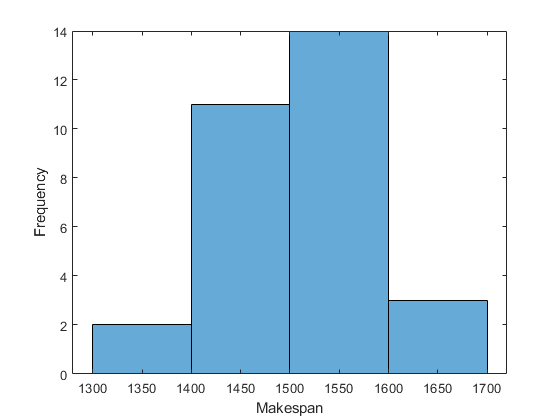

ans =   Axes with properties:

             XLim: [1280 1720]
             YLim: [0 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



% Distribution of solution quality across instances
% figure(); 
HH1.plotStepSolutionDistribution('end');

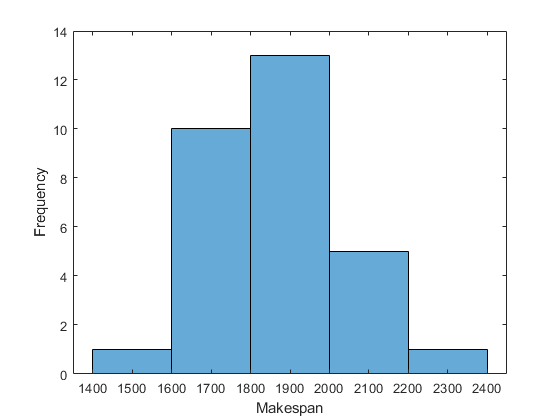

ans =   Axes with properties:

             XLim: [1350 2450]
             YLim: [0 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


HH2.plotStepSolutionDistribution('end');

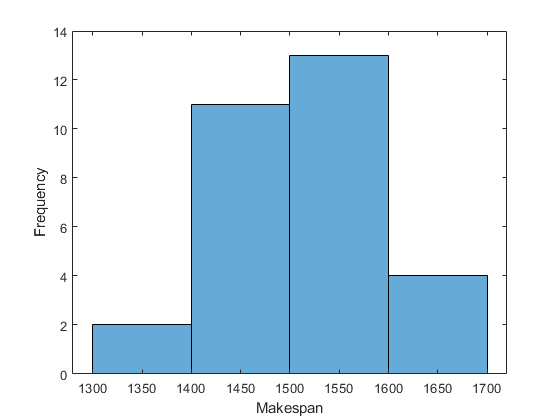

ans =   Axes with properties:

             XLim: [1280 1720]
             YLim: [0 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


HH3.plotStepSolutionDistribution('end');

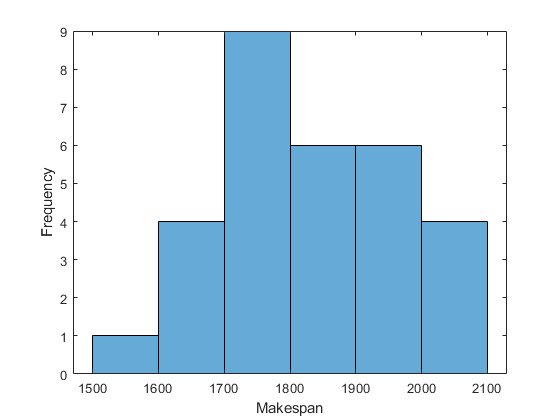

ans =   Axes with properties:

             XLim: [1470 2130]
             YLim: [0 9]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


HH4.plotStepSolutionDistribution('end');

ans =   Axes with properties:

             XLim: [1280 1720]
             YLim: [0 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


HH5.plotStepSolutionDistribution('end');


% Solution quality (overall)
nbInstances = length(trainingInstances);
perfHHs = nan(5,nbInstances);
for idx = 1 : nbInstances
    perfHHs(1,idx) = HH1_d2{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(2,idx) = HH2_d2{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(3,idx) = HH3_d2{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(4,idx) = HH4_d2{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(5,idx) = HH5_d2{idx}.solution.getSolutionPerformanceMetric; 
end
perfHHs % per instance performance

perfHHs =         1566        1469        1422        1461        1522        1512        1381        1565        1518        1526
        1801        1891        1782        1723        2021        1812        1725        1766        1799        1633
        1566        1469        1422        1461        1522        1512        1381        1565        1518        1526
        1904        1914        1680        1830        1867        1760        1781        1766        1699        1908
        1566        1469        1422        1461        1522        1512        1381        1565        1518        1526


mean(perfHHs,2) % mean performance

ans = 	1.0e+03 *

    1.4942
    1.7953
    1.4942
    1.8109
    1.4942


7. Add another RBSHH, using 5 rules and 2 features. Train it for 50 iterations with the same dataset and number of agents as before. Add these results to the comparison. Does performance improve?

HHprops = struct('nbRules',5,'selectedFeatures',[1 4]); % Features may vary
HH6 = ruleBasedSelectionHH(HHprops)

HH6 = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor/OutputPackager/isolatedDisplaying
  In matlab.internal.editor/OutputPackager/getStringFromVar
  In matlab.internal.editor/OutputPackager/getTruncatedStringFromVar
  In matlab.internal.editor/OutputPackager/packageVarOther
  In matlab.internal.editor/OutputPackager/packageVar
  In matlab.internal.editor/OutputPackager/packageOneOutput
  In matlab.internal.editor/OutputPackager/packageEachOutput
  In matlab.internal.editor/OutputPackager/packageOutputs
  In matlab.internal.editor/EvaluationOutputsService/outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)EvaluationOutputsService.outputStreamEvent(src,ev

trainingParams.maxIter = 50;
HH6.trainingInstances = trainingInstances;
HH6.train(trainingMethod,trainingParams)


[  18:41:31] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 25
              maxIter: 50
          maxStagIter: 50
             selfConf: 2.1000
           globalConf: 2.1000
          unifyFactor: 0.5000
      numberVariables: 15
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.2000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 4621
         ... Initialisation completed!

[Step     2] Gl

ans =     0.7216
    0.1175
    0.5393
    0.3820
    0.8480
         0
    0.5083
    0.2673
    0.2975
    0.5082


disp(HH6)

Displaying information about the Trained HH:
	Target problem:      JSSP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 10 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 25
           maxIter: 50
       maxStagIter: 50
          selfConf: 2.1000
        globalConf: 2.1000
       unifyFactor: 0.5000

	Performance achieved:	4519.00
	Time taken:	375.24
	Evaluations taken:	1300
	Iterations performed:	50
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	5
	Usable features:	2 (  1  4  )
	Usable solvers:	4 (  1  2  3  4  )

Current model:
    RuleID      F1         F4       HeuristicID
    ______    _______    _______    ___________

      1 


HH6_d2 = HH6.solveInstanceSet(JSSPInstancesSecond)

HH6_d2 = 1×30 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


perfHH6 = nan(1,nbInstances);
for idx = 1 : nbInstances
    perfHH6 (1,idx) = HH6_d2{idx}.solution.getSolutionPerformanceMetric;         
end
[perfHHs; perfHH6] % per instance performance

ans =         1566        1469        1422        1461        1522        1512        1381        1565        1518        1526
        1801        1891        1782        1723        2021        1812        1725        1766        1799        1633
        1566        1469        1422        1461        1522        1512        1381        1565        1518        1526
        1904        1914        1680        1830        1867        1760        1781        1766        1699        1908
        1566        1469        1422        1461        1522        1512        1381        1565        1518        1526
        1566        1469        1422        1461        1522        1512        1381        1565        1518        1526


mean([perfHHs;perfHH6],2) % mean performance

ans = 	1.0e+03 *

    1.4942
    1.7953
    1.4942
    1.8109
    1.4942
    1.4942


8. How do all models fare for the remaining 20 instances of the first dataset?

% All models on the remainder of the dataset
testingInstances = JSSPInstancesFirst(11:end);
HH1_d1 = HH1.solveInstanceSet(testingInstances)

HH1_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH2_d1 = HH2.solveInstanceSet(testingInstances)

HH2_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH3_d1 = HH3.solveInstanceSet(testingInstances)

HH3_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH4_d1 = HH4.solveInstanceSet(testingInstances)

HH4_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH5_d1 = HH5.solveInstanceSet(testingInstances)

HH5_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}


HH6_d1 = HH6.solveInstanceSet(testingInstances)

HH6_d1 = 1×20 cell array
    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}    {1×1 JSSPInstance}



% Solution quality (overall)
nbInstances = length(testingInstances);
perfHHs = nan(6,nbInstances);
for idx = 1 : nbInstances
    perfHHs(1,idx) = HH1_d1{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(2,idx) = HH2_d1{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(3,idx) = HH3_d1{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(4,idx) = HH4_d1{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(5,idx) = HH5_d1{idx}.solution.getSolutionPerformanceMetric; 
    perfHHs(6,idx) = HH6_d1{idx}.solution.getSolutionPerformanceMetric; 
end
perfHHs % per instance performance

perfHHs =    469   471   526   524   450   433   404   457   440   366   554   427   555   400   450   434   655   453   561   500
   480   575   573   466   450   433   418   457   514   366   554   507   554   400   538   535   655   575   561   500
   469   471   458   524   409   433   404   457   440   366   554   419   555   406   450   434   586   453   561   500
   469   471   458   524   450   452   404   457   440   366   554   419   555   365   450   435   596   437   561   500
   469   467   526   524   450   433   404   456   440   366   587   427   603   400   450   435   596   437   561   500
   469   467   526   524   450   433   404   456   440   366   587   427   603   372   450   435   665   437   561   500


mean(perfHHs,2) % mean performance

ans =   476.4500
  505.5500
  467.4500
  468.1500
  476.5500
  478.6000
